# Module 7: Single-particle tracking

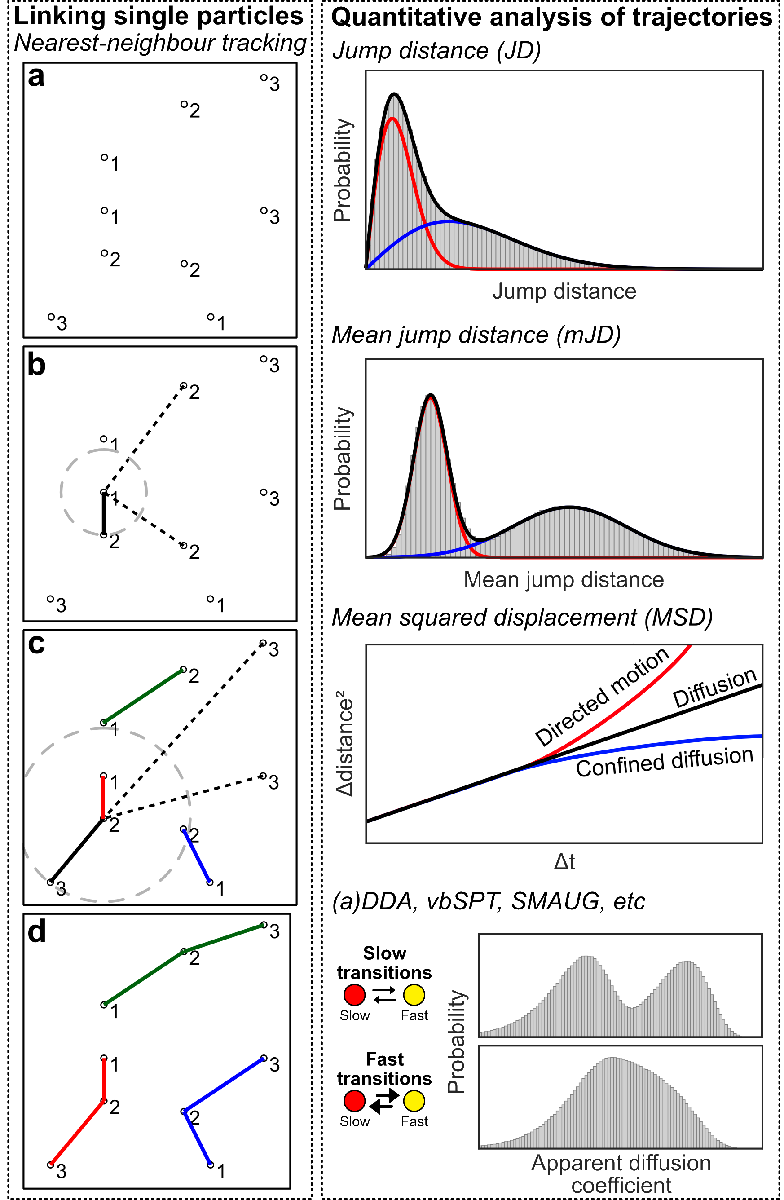

In single-particle tracking, a single emitter has moved throughout the field of view over multiple time points. The goal of this module is to figure out what trajectory these particles took, and how we can quantitatively interpret these.

We note that some of the computational efforts in this module are similar to Module 3 (localization merging), as they are both based on nearest-neighbour methods.

## Variable initiation

%Load data
data = commonFunctions.readCSVThunderSTORM('Data\DualBeadsData.csv');

%Define some variables
maxDistance = 2000; %Max distance between points per frame

## Trajectory creation - full datasets

The tracking of this data is identical to the tracking explained in module 3. Therefore, we will use the function created there. To understand how the trajectories are created, please look at module 3.

%Now we can put it inside two for-loops: looping over all frames and over all 
%maxOffFrames
tracked_data = [data zeros(size(data,1),2)];
tracksCounter = 1;

for fr = 0:max(tracked_data(:,1))-1
    [tracked_data,tracksCounter] = commonFunctions.creating_trajectories(tracked_data,fr,fr+1,maxDistance,tracksCounter);
end


## Visualisation of trajectories

Now that we have all the tracks, we can start investigation by simply visualising them. While this is not quantitative, it does provide information on the dataset.

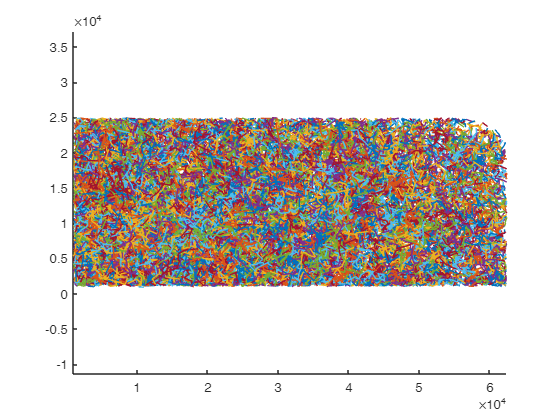

%Now we visualise all tracks based on their trackID
figure()
hold on
for tr = 1:max(tracked_data(:,5))
    trackplot = tracked_data(tracked_data(:,5)==tr,:);
    plot(trackplot(:,2),trackplot(:,3));
end
axis equal

## Quantification of sptPALM data

Now that we have the trajectories, we have to interpret these. We show here two different methods to quantify trajectory data: jump distance (JD) histogram analysis, and mean jump distance (mJD) histogram analysis.

Briefly, the JD histogram plots all jump-distances of all jumps of all tracks. The mJD histogram requires the mean jump-distance of every track, and then plots those as a histogram.

## Jump distance (JD) histogram analysis

Analysis of jump distance (JD) histograms first requires the calculation of JDs. This is done by looking at every trajectory that has been found, and calculting the distance the emitter moved from frame-to-frame.

These JDs are then visualised in a histogram, and this histogram can be fitted with a Rayleigh distribution. Additionally, since we expect two populations in our data set, we fit the dataset with double Rayleigh distributions. We also show that fitting a single Rayleigh population does not provide a good fit, indicating that indeed two populations are present.

Because the JDs are already calculated during the tracking (see module 3), we require one extra functions for this: to define the distribution of the jump distances, called 'rayleigh_dist', which can be found on line 169

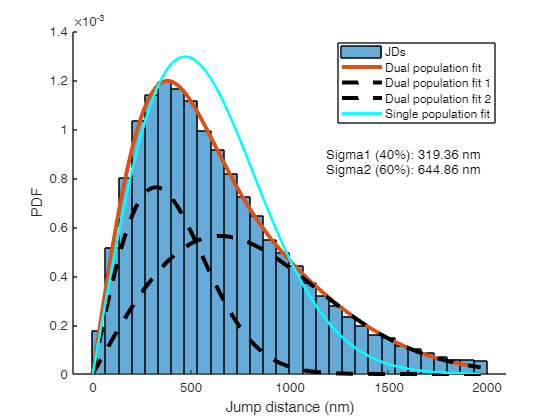

% The JD values can be extracted from the tracked_data, but we must take
% into account that some localizations are not part of trajectories and
% need to be filtered out.
jd_information = tracked_data(tracked_data(:,5)>0,:);

% Additionally, we must take care that if we allow for blinking frames, the
% calculated JD is over >1 frame, and should be discarded for honest
% analysis. We filter these out by looping over all rows and replacing the
% JD value by -1, if two concequetive entries belong to the same trajectory
% but differ more than 1 frame.
% First, we sort the information by trajectory-ID, then on frame
jd_information = sortrows(jd_information,[5,1]);
%Loop over all ids
for i = 1:size(jd_information,1)-1
    %Check if it's the same trajectory
    if jd_information(i,5) == jd_information(i+1,5)
        %Check if it's more than 1 frame difference
        if jd_information(i+1,1) > jd_information(i,1)+1
            %If so, replace the JD by a value of -1, which can be filtered
            %out.
            jd_information(i,6) = -1;
        end
    end
end
%Finally, we can get a jd list:
jds = jd_information(jd_information(:,6)>0,6);

%Now we want to bin these JDs in a histogram, and fit this. We will do the
%binning with the histcounts function. Additionally, this is a probability
%density function, so we normalise as PDF
nrbins = 30;
[jds_y, BinEdges] = histcounts(jds,linspace(0,maxDistance,nrbins+1),'Normalization','pdf');
% We have to calculate the center of the bins
jds_x = BinEdges(2:end)-(BinEdges(2)-BinEdges(1))/2;

% And now we fit the data with the double rayleigh distribution
fo = fitoptions('Method','NonlinearLeastSquares','StartPoint',[100,300,0.5],'TolFun',1e-9);
ft = fittype( @(s1,s2,a,x) double_rayleigh_dist(x,s1,s2,a) ,'options',fo);
[fcurveDouble] = fit(jds_x',jds_y',ft);

% We also fit it with the single population, to show that this fit fails
fo = fitoptions('Method','NonlinearLeastSquares','StartPoint',[100],'TolFun',1e-9);
ft = fittype( @(s,x) rayleigh_dist(x,s) ,'options',fo);
[fcurveSingle] = fit(jds_x',jds_y',ft);

% Next, we draw the fitted model by providing the computed sigma parameter 
% on top of the JD values histogram.
xshow = linspace(0, max(jds_x), 1000);
yshowDouble = double_rayleigh_dist(xshow, fcurveDouble.s1, fcurveDouble.s2, fcurveDouble.a);
yshowDoubleFirst = rayleigh_dist(xshow, fcurveDouble.s1)*fcurveDouble.a;
yshowDoubleSecond = rayleigh_dist(xshow, fcurveDouble.s2)*(1-fcurveDouble.a);

%We also calculate it for the single population
yshowSingle = rayleigh_dist(xshow, fcurveSingle.s);

%And we plot the figure with the histogram, the fitted model, and some text
figure();
hold on
histogram(jds,linspace(0,maxDistance,nrbins+1),'Normalization','pdf', 'DisplayName','JDs');
plot(xshow,yshowDouble,'LineWidth',3, 'DisplayName','Dual population fit');
plot(xshow,yshowDoubleFirst,'k--','LineWidth',3, 'DisplayName','Dual population fit 1');
plot(xshow,yshowDoubleSecond,'k--','LineWidth',3, 'DisplayName','Dual population fit 2');
plot(xshow,yshowSingle,'c-','LineWidth',2,'DisplayName','Single population fit');
xlabel('Jump distance (nm)');
ylabel('PDF');
legend()
text(max(xshow)*0.6,max(yshowDouble)*0.75,['Sigma1 (' num2str(round(fcurveDouble.a*100)) '%): ' num2str(round(fcurveDouble.s1,2)), ' nm']);
text(max(xshow)*0.6,max(yshowDouble)*0.7,['Sigma2 (' num2str(round(100-fcurveDouble.a*100)) '%): ' num2str(round(fcurveDouble.s2,2)), ' nm']);

## Mean jump distance (MJD) histogram analysis

The analysis of mean jump distances is similar to JD analysis, but the mean jump distance for every track is calculated instead. Therefore, a for-loop is performed over every track, and the mean JD of this track is calculated based on the JDs calculated earlier.

Next, these MJDs are plotted as a histogram, and it is fitted with 2 Gaussian distributions.

This again requires a few functions, which are 'calculate_MJD' on line 178, 'gaussian_dist' on line 230, and 'double_gaussian_dist' on line 239.

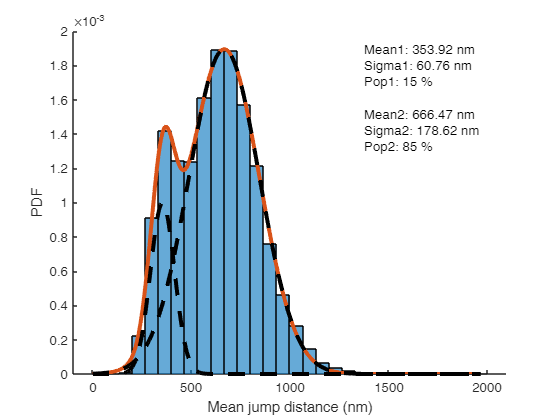

% The MJD values are computed by using the calculate_MJD function. 
% As there are still some events which will not have MJD value computed, 
% they will be filtered out.
mjd_calculated = calculate_MJD(tracked_data);
mjds = mjd_calculated(mjd_calculated(:,7) > -1, 7);

% We filter the MJDs to only include trajectories between 6 and 20 frames
% long
mjds_filtered = [];
for t = 1:max(mjd_calculated(:,5))
    trackLength = size(mjd_calculated(mjd_calculated(:,5) == t,:),1);
    %If it's long enough, we extend the mjds_filtered list with the mjds
    if trackLength > 5 && trackLength < 21
        mjds_filtered = [mjds_filtered; mjd_calculated(mjd_calculated(:,5) == t,7)];
    end
end

%We replace the mjds array with the long trajectories only
mjds= mjds_filtered; 

% We perform very similar operations as on the JD histogram:
% We will do the binning with the histcounts function. Additionally, 
% this is a probability density function, so we normalise as PDF
nrbins = 30;
[mjds_y, BinEdges] = histcounts(mjds,linspace(0,maxDistance,nrbins+1),'Normalization','pdf');
% We have to calculate the center of the bins
mjds_x = BinEdges(2:end)-(BinEdges(2)-BinEdges(1))/2;

% And now we fit the data with the Gaussian distribution specified as
% function down
% We use the mean and std of the mjds as start values for the fit
fo = fitoptions('Method','NonlinearLeastSquares','StartPoint',[400,50,600,50,0.5],'TolFun',1e-9,'Lower',[0,0,0,0,0]);
ft = fittype( @(m1,s1,m2,s2,a,x) double_gaussian_dist(x,m1,s1,m2,s2,a) ,'options',fo);
[fcurveMJD] = fit(mjds_x',mjds_y',ft);

% Next, we draw the fitted model by providing the computed 
% parameter values on top of the MJD values histogram.
xshow = linspace(0, max(mjds_x), 1000);
yshowDouble = double_gaussian_dist(xshow, fcurveMJD.m1, fcurveMJD.s1, fcurveMJD.m2, fcurveMJD.s2, fcurveMJD.a);
%And we also show the individual gaussian curves
yshowDoubleFirst = gaussian_dist(xshow,fcurveMJD.m1, fcurveMJD.s1)*fcurveMJD.a;
yshowDoubleSecond = gaussian_dist(xshow,fcurveMJD.m2, fcurveMJD.s2)*(1-fcurveMJD.a);

%And we plot the figure with the histogram, the fitted model, and some text
figure();
hold on
histogram(mjds,linspace(0,maxDistance,nrbins+1),'Normalization','pdf');
plot(xshow,yshowDouble,'LineWidth',3);
plot(xshow,yshowDoubleFirst,'k--','LineWidth',3);
plot(xshow,yshowDoubleSecond,'k--','LineWidth',3);
xlabel('Mean jump distance (nm)');
ylabel('PDF');
text(max(xshow)*0.7,max(yshowDouble)*0.95,{['Mean1: ' num2str(round(fcurveMJD.m1,2)) ' nm'];['Sigma1: ' num2str(round(fcurveMJD.s1,2)), ' nm'];['Pop1: ' num2str(round(100*fcurveMJD.a)), ' %']});
text(max(xshow)*0.7,max(yshowDouble)*0.75,{['Mean2: ' num2str(round(fcurveMJD.m2,2)) ' nm'];['Sigma2: ' num2str(round(fcurveMJD.s2,2)), ' nm'];['Pop2: ' num2str(round(100-100*fcurveMJD.a)), ' %']});

## Visualisation of trajectories - with diffusion data

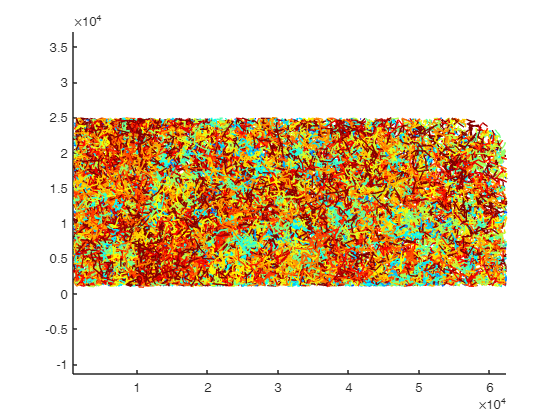

% As each trajectory has JD and MJD values calculated, we can use, e.g. JD information 
% to color code the trajectories on the plot.

% First we get the colormap values of the colormap 'jet'
% This gives us a colormap of a length corresponding to the 90th mjd
% percentile found in the dataset - meaning that we can look up a color that
% corresponds to every mjd during plotting
cmapinfo = jet(round(prctile(mjd_calculated(:,7),90)));

figure()
hold on
for tr = 1:max(mjd_calculated(:,5))
    trackplot = mjd_calculated(mjd_calculated(:,5)==tr,:);
    %We plot the track, with the color based on the mjd of this track
    % We add a value of 1 to prevent errors when trying to look up a zero-index
    % and we ensure it won't be larger than the 90th percentile by looking
    % at the size of cmapinfo
    plot(trackplot(:,2),trackplot(:,3),'Color',cmapinfo(min(round(trackplot(1,7))+1,size(cmapinfo,1)),:));
end
axis equal

## Function declaration

function out = rayleigh_dist(x,sigma)
out = x./(sigma^2) .* exp(-(x.^2)./(2*sigma^2));
end
function out = double_rayleigh_dist(x,sigma1,sigma2,a)
out = a.*(x./(sigma1^2) .* exp(-(x.^2)./(2*sigma1^2)))+(1-a).*(x./(sigma2^2) .* exp(-(x.^2)./(2*sigma2^2)));
end


% This function computes the mean jump distance (MJD) for each trajectory. 
function dataMJD = calculate_MJD(data)
    % First, we repeat the JD filtering as explained before
    % We must take care that if we allow for blinking frames, the
    % calculated JD is over >1 frame, and should be discarded for honest
    % analysis. We filter these out by looping over all rows and replacing the
    % JD value by -1, if two concequetive entries belong to the same trajectory
    % but differ more than 1 frame.
    % First, we sort the information by trajectory-ID, then on frame
    jd_information = sortrows(data,[5,1]);
    %Loop over all ids
    for i = 1:size(jd_information,1)-1
        if jd_information(i,5)>0
            %Check if it's the same trajectory
            if jd_information(i,5) == jd_information(i+1,5)
                %Check if it's more than 1 frame difference
                if jd_information(i+1,1) > jd_information(i,1)+1
                    %If so, replace the JD by a value of -1, which can be filtered
                    %out.
                    jd_information(i,6) = -1;
                end
            end
        end
    end

    % Then we append the columns at the end of the array filled with -1, 
    dataMJD = [jd_information ones(size(jd_information,1),1)*-1];
    % We create an array with trajectory id values. It will be used to 
    % iterate over data trajectory-wise rather than row-wise in order to 
    % speed up the computation.
    track_ids = unique(dataMJD(:,5));
    %Remove the zero-entry
    track_ids(track_ids == 0) = [];

    % For each trajectory we are calculating the MJD value. We have to keep in 
    % mind that in trajectories can have 0-value-JDs, in case there are
    for t_index = 1:size(track_ids,1)
        t_id = track_ids(t_index);
        track_array = dataMJD(dataMJD(:,5) == t_id,:);
        nonzero_jds = track_array(track_array(:,6)>0,6);
        mjdvalue = mean(nonzero_jds);
        dataMJD(dataMJD(:,5) == t_id, 7) = mjdvalue;
    end
    
    %returns frame, x, y, intensity, track_id, jd, mjd
end



% MJD distribution follows the Gaussian (normal) distribution. In order to 
% fit the MJD histogram we provide this method to compute Gaussian 
% distributions when the independent variable (x) the mean (mu) 
% and standard deviation (sigma) values are provided.   
function out = gaussian_dist(x, mu, sigma)
    out = 1/(sigma*sqrt(2*pi)).*exp(-0.5.*((x-mu)./sigma).^2);
end


% If the particle exist in more than one dynamic state, they can be fitted with multiple normal distributions. 
% Here we provide the method which allows to fit a double normal distribution as an example. 
% Each normal distribution has its own mean and standard deviation value. 
% Additionally we have to add a fraction paramter (a). All fractions have to add up to 1.
function out = double_gaussian_dist(x, mu1, sigma1, mu2, sigma2, a)
    out = (a/(sigma1*sqrt(2*pi)).*exp(-0.5.*((x-mu1)./sigma1).^2))+((1-a)/(sigma2*sqrt(2*pi)).*exp(-0.5.*((x-mu2)./sigma2).^2));
end